# Machine Learning - Assignment 1

### Author: Benjamin Brodwolf (benjamin.brodwolf@students.fhnw.ch)

### Task 1

"*Load and visualize the dataset house_data.csv.*"

options = delimitedTextImportOptions("Delimiter",{'"',','},"ConsecutiveDelimitersRule","join", "DataLines",2, "NumVariables",21, "ExtraColumnsRule","ignore", "LeadingDelimitersRule","ignore", "VariableNamesLine",1);
options = setvartype(options,2,"datetime");
options = setvartype(options,[1,3:8,13:21],'double');
options = setvartype(options,[11,12,15,16,17],"categorical");
options = setvartype(options,[9,10],"logical");
options = setvaropts(options,2,"InputFormat",'yyyyMMdd''T''HHmmss',"DatetimeFormat",'d MMM yyyy');
data = readtable("house_data.csv",options)

data = 21613×21 table
        id           date          price       bedrooms    bathrooms    sqft_living     sqft_lot     floors    waterfront    view     condition    grade    sqft_above    sqft_basement    yr_built    yr_renovated    zipcode     lat       long      sqft_living15    sqft_lot15
    __________    ___________    __________    ________    _________    ___________    __________    ______    __________    _____    _________    ____

### Task 2 

*"Estimate ‘price‘ using 'sqft_living‘ as the only variable. Visualize the regression line together with the datapoints. Generate a Tukey-Anscombe-Plot and interpret what it shows."*

% loading the prices and sqft_living
prices = table2array( data(:,"price") );
sqft_living = table2array( data(:, "sqft_living"));

figure;
% Plot the data sqft_living and prices
plot(sqft_living, prices, 'o', 'MarkerSize', 1); 
title({'Task2','Plot Price & Square feet of Living'});
ylabel('House Prices on 10,000s'); 
xlabel('Living Areas Sq. Ft.');

m = length(prices);

% Add intercept term to sqliving
sqft_living = [ones(m, 1) sqft_living];

% Estimate the prices with sqft_living
theta = normalEqn(sqft_living, prices);

fprintf('Theta computed from the normal equations:\n%f,\n%f',theta(1),theta(2))

Theta computed from the normal equations:
-43580.743095,
280.623568

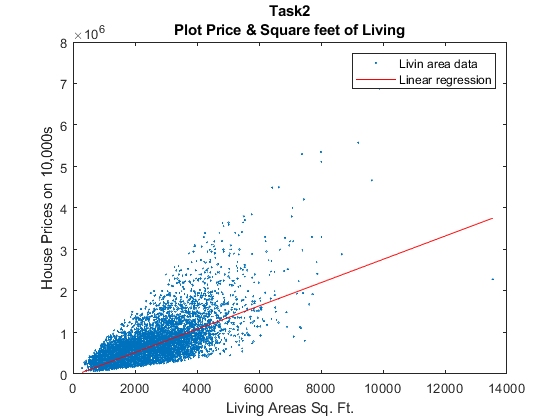


% Plot the linear fit
hold on; % keep previous plot visible
plot(sqft_living(:,2), sqft_living*theta, 'r-');
legend('Livin area data', 'Linear regression');
hold off;

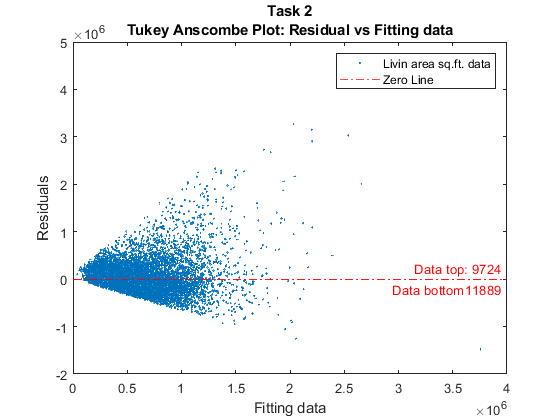

Above and under the "Zero Line" 
 Top:		 9724
 Bottom:	 11889
 Std.dev.:	 1530.886181

prices_pred = sqft_living*theta; 

residual = prices - prices_pred;

tukeyAnscombePlot(prices_pred, residual, "2");

We see different error varieties:

- The points should be evenly distributed around the '**Zero Line**'

- The **Cone-shape**

 It can possibly be fixed with the help of a log transformation.

### Task 3

*"Apply a log-transformation to get the output variable log(‘price‘) and  repeat task 2. Additionally, create a histogram of the residuals (number of bins = 100).*

*Calculate the standard deviation of the residuals and interpret the created plots and values."*

% clean loading of the data
prices = table2array( data(:,"price") );
sqft_living = table2array( data(:, "sqft_living"));


prices_log = log(prices);

m = length(prices);

% Add intercept term to sqliving
sqft_living = [ones(m, 1) sqft_living];

theta_log = normalEqn(sqft_living, prices_log);

prices_log_pred = sqft_living*theta_log;

#### Plot log(prices) with Square Feets of living with Lineare Regression

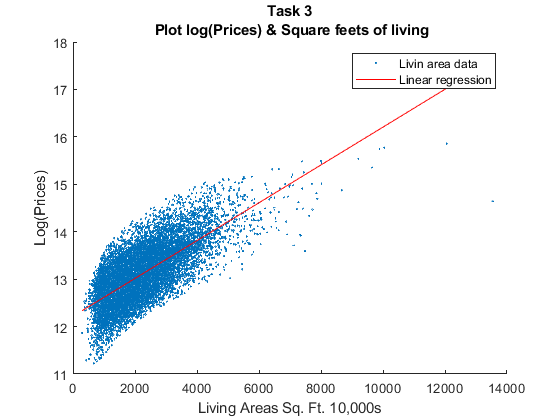


figure;
hold on; % for new figure
plot(sqft_living(:,2), prices_log, 'o', 'MarkerSize', 1); % Plot the data
title({'Task 3',' Plot log(Prices) & Square feets of living'});
ylabel('Log(Prices)');
xlabel('Living Areas Sq. Ft. 10,000s'); 

plot(sqft_living(:,2), sqft_living*theta_log, 'r-')
legend('Livin area data', 'Linear regression')

#### Plot Tukey Anscomble Plot

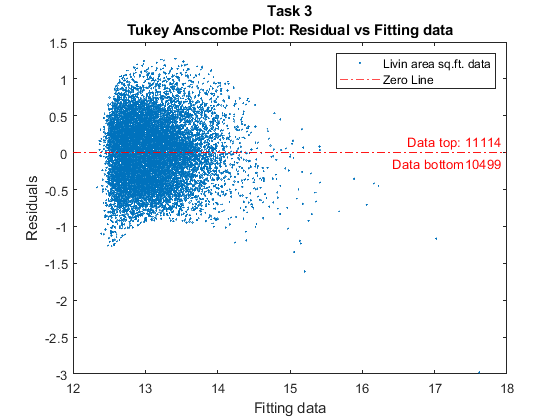

Above and under the "Zero Line" 
 Top:		 11114
 Bottom:	 10499
 Std.dev.:	 434.870670

residual_log = prices_log - prices_log_pred;

tukeyAnscombePlot(prices_log_pred, residual_log, "3");

The log transformation has fixed the cone shape and the distribution of the data is much better. We can also count the data between the "**Zero Line**" and see it is more balanced then before. 

But the points have still a top high align to the left side.

#### Create a histogram of the residuals (number of bins = 100).

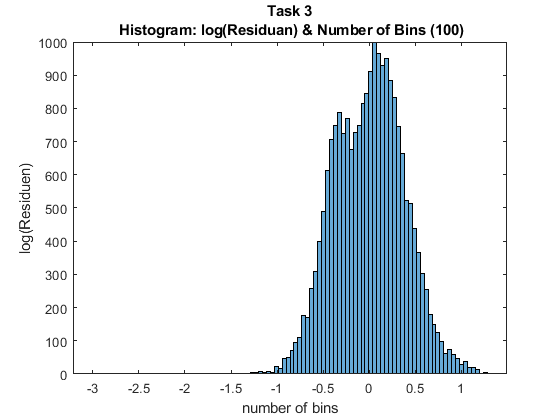

figure;
nbins = 100;
histogram(residual_log, nbins);
title({'Task 3',' Histogram: log(Residuan) & Number of Bins (100)'})
ylabel('log(Residuen)'); % Set the y-axis label
xlabel('number of bins'); % Set the x-axis label
hold on; 

The histogram shows a skew to the left. It also has smaller outliers to see on the tops.

fprintf("The Standard deviation of the residuals with log('price') is: " + std(residual_log));

The Standard deviation of the residuals with log('price') is: 0.37852

The calculation of the standard deviation from the price with logarithmic is not very bad - but according to the view of the histogram, there could be adjustments and thus make the standard deviation even better or smaller.

## Task 4

*"Calculate the ‘mean absolute percentage error’ (MAPE) and the ‘median absolute percentage error’ (MdAPE) for the model of task 3. Visualize the distribution of the absolute percentage errors for the models of tasks 2 and 3."*

% "Absolute Percentage Error (APE)" of Task 3.
prices_log = log(prices);
LOG_APE = abs( (prices_log-prices_log_pred)./prices_log );

LOG_MAPE = mean( LOG_APE );
fprintf('The MAPE of Task 3 is %f (%4.2f%%) ' , LOG_MAPE, LOG_MAPE*100);   % MAPE is 0.023597 -> 2.36%

The MAPE of Task 3 is 0.023597 (2.36%) 


LOG_MdAPE = median( LOG_APE );
fprintf('The MdAPE of Task 3 is %f (%4.2f%%) ' , LOG_MdAPE, LOG_MdAPE*100);  % MdAPE is 0.020879 -> 2.09%

The MdAPE of Task 3 is 0.020879 (2.09%) 

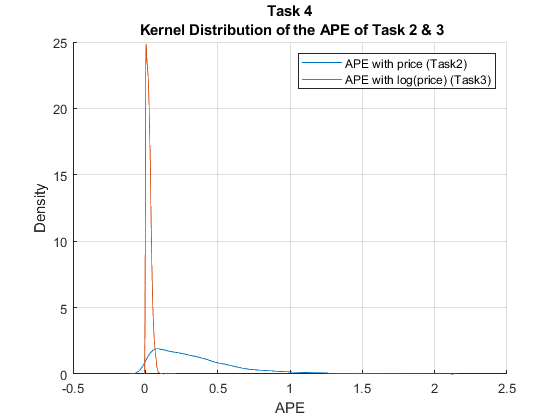

% "Absolute Percentage Error (APE)" of Task 2.
APE = abs( (prices-prices_pred)./prices );

figure;
hold on;
grid on;
ksdensity(APE);
ksdensity(LOG_APE);
title({'Task 4',' Kernel Distribution of the APE of Task 2 & 3'});
legend('APE with price (Task2)', 'APE with log(price) (Task3)');
ylabel('Density'); % Set the y-axis label
xlabel(' APE '); % Set the x-axis label
hold off;

You can clearly see that the logarithmic values from Task 3 are much denser than those without from Task 2. So we are going much better with the logarithmic values.

### Task 5

*"Investigate the spatial distribution of ‘zipcode‘ and ‘price‘ with a scatter plot by marking the geographic location (‘long‘ / ‘lat‘) of each object with a colored dot representing either ‘zipcode‘ or ‘price‘ in a suitable color-table and -scale. Discuss the relationship between the two variables."*

% load data
prices = table2array( data(:,"price") );
zipcode =  double(string(table2array( data(:,"zipcode") )));
long = table2array( data(:,"long") );
lat = table2array( data(:,"lat") );

#### Scatter plot with 'zipcode':

amount_of_zipcode = num2str(length(unique(zipcode)))

amount_of_zipcode = '70'

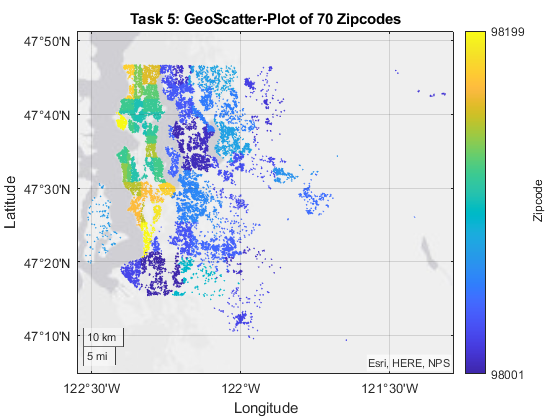

% scale zipcode between 1 to 0 for coloring
min_zipcode = min(zipcode);
max_zipcode = max(zipcode);
color = (zipcode - min_zipcode) ./ (max_zipcode-min_zipcode);

figure;
geoscatter(lat, long, zipcode./50000 ,color, 'filled');

cbar = colorbar('Ticks', [0, 1], ...
    'TickLabels', { num2str(min(zipcode), '%d') , num2str(max(zipcode), '%d')}, ...
    'TickLabelInterpreter', "tex");

ylabel(cbar, ' Zipcode');
title(['Task 5: GeoScatter-Plot of ', amount_of_zipcode ,' Zipcodes']);

The zip codes show how states and cities in the USA have been divided in zones. Here you can see how the 70 zones from Washington to Seattle have been divided. From 98001 (dark blue) to 98199 (yellow) direction to  Seattel zipcode numbers was increased.

Conclusion: The zip codes with the highest numbers (range from green to yellow) are closest to the city of Seattle.

#### Scatter plot with 'price':

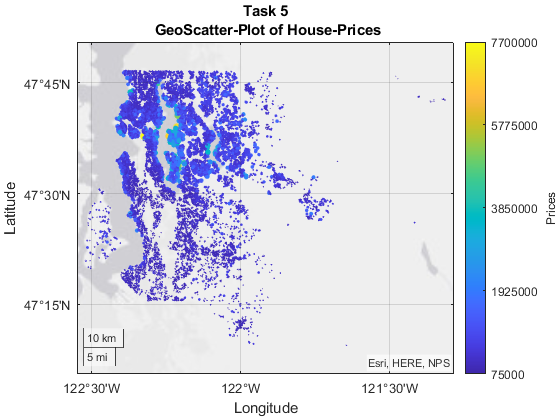

% scale prices between 1 to 0 for coloring
min_price = min(prices);
max_price = max(prices);
color = (prices - min_price) ./ (max_price-min_price);

figure;
geoscatter(lat, long, prices./200000 ,color, 'filled');

cbar = colorbar('Ticks', [0, 0.25 0.5, 0.75 1], ...
    'TickLabels', { num2str(min(prices), '%d'), num2str(max(prices)*0.25, '%d')  , num2str(max(prices)*0.5, '%d') , num2str(max(prices)*0.75, '%d') , num2str(max(prices), '%d')}, ...
    'TickLabelInterpreter', "tex");

ylabel(cbar, 'Prices');
title({'Task 5',' GeoScatter-Plot of House-Prices'});

The prices of the houses are highest in the center of the city of Seattle and are on the lake. The lighter blue spots are clearly visible. However, you do not see any yellow dots because they are rather rare and lose themselves among the many blue dots.

### Scatter plot with 'price' zoomed:

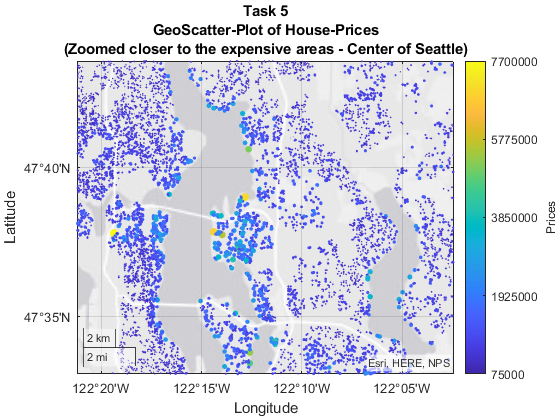

figure;
geoscatter(lat, long, prices./200000 ,color, 'filled');

cbar = colorbar('Ticks', [0, 0.25 0.5, 0.75 1], ...
    'TickLabels', { num2str(min(prices), '%d'), num2str(max(prices)*0.25, '%d')  , num2str(max(prices)*0.5, '%d') , num2str(max(prices)*0.75, '%d') , num2str(max(prices), '%d')}, ...
    'TickLabelInterpreter', "tex");

ylabel(cbar, 'Prices');
title({'Task 5','GeoScatter-Plot of House-Prices','(Zoomed closer to the expensive areas - Center of Seattle)'});
geolimits([47.551 47.726],[-122.340 -122.054])

Again the same plot as before, just zoomed into the center of Seattle. Now you can see the individual very expensive houses or the yellow dots. You can also see that the houses closest to the water are much more expensive than the others.

### Task 6

*"Feature Engineering: Find a way to encode the variable ‘zipcode‘ into additional features (e.g. using one-hot-encoding, see example on the below). Estimate log( price ) using the newly created features together with 'sqft_living‘ in a linear regression. *

*Regenerate a Tukey-Anscombe-Plot and a histogram of the residuals and calculate the values for MAPE and MdAPE and discuss the plots and the values in relation to the previous solutions."*

% load  data
prices = table2array( data(:,"price") );
zipcode =  double(string(table2array( data(:,"zipcode") )));
sqft_living = table2array( data(:, "sqft_living"));

% log the prices
prices_log = log(prices);

% create a unique list of zipcodes
uniq_zipcode = unique(zipcode);

% create the "one hot encoding" of zipcodes
[~, loc] = ismember(zipcode, uniq_zipcode);
zipcode_hot_encoding = transpose(full(ind2vec(loc')));

% add and compine [bias | sqft_living ] to the zipcode_hot_encoding
zipcode_hot_encoding = [ones(length(sqft_living), 1), sqft_living, zipcode_hot_encoding];

% create a string-list-zipcode for the table
zipcode_header = strsplit( num2str( uniq_zipcode'));

% creating the zipcode_hot_ecoding_table
zipcode_hot_encoding_table = array2table(zipcode_hot_encoding, 'VariableNames',  ["bias", "sqft_living", zipcode_header])

zipcode_hot_encoding_table = 21613×72 table
    bias    sqft_living    98001    98002    98003    98004    98005    98006    98007    98008    98010    98011    98014    98019    98022    98023    98024    98027    98028    98029    98030    98031    98032    98033    98034    98038    98039    98040    98042    98045    98052    98053    98055    98056    98058    98059    980

% estimate the log(price) with the newly created features and sqft_livin 
theta_zipcode_price = normalEqn(zipcode_hot_encoding, prices_log);

% predicted prices
prices_log_pred = zipcode_hot_encoding*theta_zipcode_price;

% calculate the residual 
residual_log = prices_log - prices_log_pred;

#### Tukey Anscomble Plot of residuals 

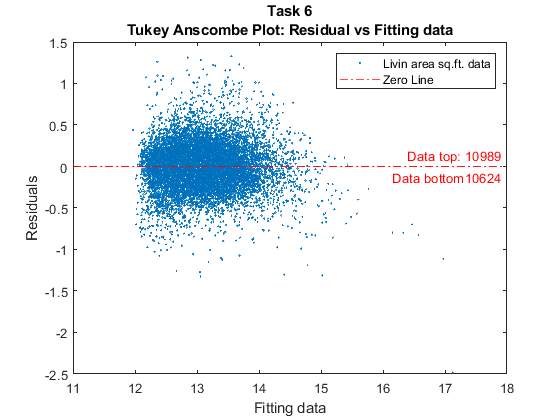

Above and under the "Zero Line" 
 Top:		 10989
 Bottom:	 10624
 Std.dev.:	 258.093975

tukeyAnscombePlot(prices_log_pred, residual_log, "6");

The scape of the distribution looks definitely better, which is positive good, but the balance of the distribution has changed little to be better.

#### Histogram of the residuals

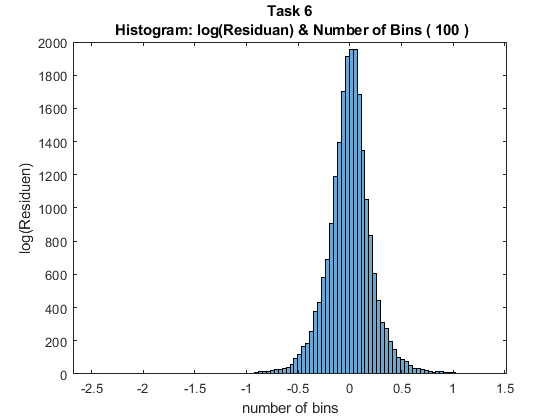

figure;
nbins = 100;
histogram(residual_log, nbins);
title({'Task 6',' Histogram: log(Residuan) & Number of Bins ( 100 )'});
ylabel('log(Residuen)'); 
xlabel('number of bins');

The histogram also looks great like the Tukey-Anscombe plot, it has also got a cleaner shape. But the histogram is still skewed on the left.

fprintf("The Standard deviation of the residuals is: " + std(residual_log));

The Standard deviation of the residuals is: 0.22166

The standard deviation is better then before (see Task 3).

#### Calculate the values for MAPE and MdAPE

% "Absolute Percentage Error (APE)" of Task 6.
prices_log = log(prices);
LOG_APE = abs( (prices_log-prices_log_pred)./prices_log );

LOG_MAPE = mean( LOG_APE );
fprintf('MAPE of Task 6 is %f (%4.2f%%) ' , LOG_MAPE, LOG_MAPE*100);   % MAPE is 0.012250 -> 1.22%

MAPE of Task 6 is 0.012250 (1.22%) 


LOG_MdAPE = median( LOG_APE );
fprintf('MdAPE of Task 6 is %f (%4.2f%%) ' , LOG_MdAPE, LOG_MdAPE*100);  % MdAPE is 0.008987 -> 0.90%

MdAPE of Task 6 is 0.008987 (0.90%) 

The mean and median relative distance of the true measured values is accordingly **1.22%** (MAPE) and **0.90%** (MdAPE).

### Task 7

Repeat all steps of task 6) using [‘bedrooms‘, ‘bathrooms‘, ‘grade‘, ‘yr_built'] as additional features. Discuss the outcome differences between tasks 6) and 7).

% load  data
prices = table2array( data(:,"price") );
sqft_living = table2array( data(:, "sqft_living"));
zipcode =  double(string(table2array( data(:,"zipcode") )));
bedrooms =  double(string(table2array( data(:,"bedrooms") )));
bathrooms =  double(string(table2array( data(:,"bathrooms") )));
grade =  double(string(table2array( data(:,"grade") )));
yr_built =  double(string(table2array( data(:,"yr_built") )));

% log the prices
prices_log = log(prices);

% create the "one hot encoding" of the features
zipcode_ohe = OneHotEncoding(zipcode);
bedrooms_ohe = OneHotEncoding(bedrooms);
bathrooms_ohe = OneHotEncoding(bathrooms);
grade_ohe = OneHotEncoding(grade);
yr_built_ohe = OneHotEncoding(yr_built);

% add and compine [bias | sqft_living ] to the zipcode_hot_encoding
many_features_ohe = [ones(length(prices), 1), sqft_living, zipcode_ohe, bedrooms_ohe, bathrooms_ohe, grade_ohe, yr_built_ohe]

many_features_ohe =            1        1180           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           1        2570           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0       


% estimate the log(price) with the newly created features and sqft_livin 
theta_many_features_price = normalEqn(many_features_ohe, prices_log);

% predicted prices
prices_many_features_pred = many_features_ohe*theta_many_features_price;

% calculate the residual 
residual_many_features_log = prices_log - prices_many_features_pred;

#### Tukey Anscomble Plot of residuals 

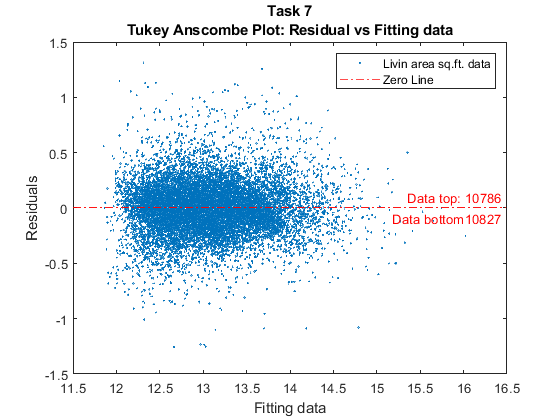

Above and under the "Zero Line" 
 Top:		 10786
 Bottom:	 10827
 Std.dev.:	 28.991378

tukeyAnscombePlot(prices_many_features_pred, residual_many_features_log, "7");

The scattering of the data points is now even broader and still very even. The balance looks great, as the distribution between the zero line now has a much lower value.

#### Histogram of the residuals

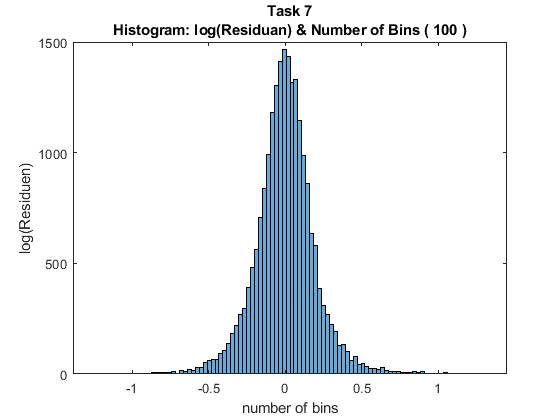

figure;
nbins = 100;
histogram(residual_many_features_log, nbins);
title({'Task 7','Histogram: log(Residuan) & Number of Bins ( 100 )'});
ylabel('log(Residuen)'); 
xlabel('number of bins'); 
hold on; 

The histogram is very well balanced. No left or right skewed anymore.

fprintf("The Standard deviation of the residuals is: " + std(residual_many_features_log));

The Standard deviation of the residuals is: 0.19925

The standard deviation is better then before (see Task 3).

#### Calculate the values for MAPE and MdAPE

% "Absolute Percentage Error (APE)" of Task 6.
LOG_APE = abs( (prices_log-prices_many_features_pred)./prices_log );

LOG_MAPE = mean( LOG_APE );
fprintf('MAPE of Task 7 is %f (%4.2f%%) ' , LOG_MAPE, LOG_MAPE*100);   % MAPE is 0.011048 -> 1.12%

MAPE of Task 7 is 0.011048 (1.10%) 


LOG_MdAPE = median( LOG_APE );
fprintf('MdAPE of Task 7 is %f (%4.2f%%) ' , LOG_MdAPE, LOG_MdAPE*100);  % MdAPE is 0.008143 -> 0.81%

MdAPE of Task 7 is 0.008143 (0.81%) 

The mean and median relative distance of the true measured values is accordingly **1.12%** (MAPE) and **0.81%** (MdAPE) and a little lower then before (see Task 6).

#### Task 8

"Recreate the model of task 7) with the normal equation for linear regression and regularize it for a suitable range of the regularization parameter ...."

% load  data
prices      =                table2array( data(:,"price") );
sqft_living =                table2array( data(:, "sqft_living"));
zipcode     =  double(string(table2array( data(:,"zipcode") )));
bedrooms    =  double(string(table2array( data(:,"bedrooms") )));
bathrooms   =  double(string(table2array( data(:,"bathrooms") )));
grade       =  double(string(table2array( data(:,"grade") )));
yr_built    =  double(string(table2array( data(:,"yr_built") )));

% create the "one hot encoding" of the features
zipcode_ohe     = OneHotEncoding(zipcode);
bedrooms_ohe    = OneHotEncoding(bedrooms);
bathrooms_ohe   = OneHotEncoding(bathrooms);
grade_ohe       = OneHotEncoding(grade);
yr_built_ohe    = OneHotEncoding(yr_built);

% add and compine one-hots-encodings 
sqft_living         = (sqft_living - min(sqft_living)) ./ (max(sqft_living)- min(sqft_living));
many_features_ohe   = [ones(length(prices), 1) sqft_living zipcode_ohe bedrooms_ohe bathrooms_ohe grade_ohe yr_built_ohe]

many_features_ohe =     1.0000    0.0672         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000    0.1721         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         


% shuffel rows
many_features_ohe   = many_features_ohe(randperm(size(many_features_ohe,1)),:);

% create random a train (80%) and test (20%) set
size_train  = round(length(many_features_ohe)*0.8);
size_test   = round(length(many_features_ohe)*0.2);

many_features_train     = many_features_ohe(1:size_train,:);
many_features_test      = many_features_ohe(size_train+1:end,:);

% log the prices
prices_log  = log(prices);

% the true y
prices_log_train    = prices_log(1:size_train,:);
prices_log_test     = prices_log(size_train+1:end, :);

#### Selecting lambda using a test set

lambda_vec = [0 0.001 0.002 0.003 0.004 0.005 0.006 0.007 0.008 0.009 0.01 0.2 0.04 0.5 0.6 0.7 0.8 0.9 1 2 3 4 5 6 7 8 9 10 15 20 30 50 70 90 100 150];

m = length(lambda_vec);

thetas_sum       = zeros(size(lambda_vec,2),1);
prices_test_pred = zeros(size(many_features_test,1), m);
 
for i=1:m
   lambda = lambda_vec(i);
 
   theta         = normalEqnLambda(many_features_train, prices_log_train, lambda);
   thetas_sum(i) = sum(theta(2:end) .^ 2); %sum(theta.^2)

   prices_test_pred(:,i) = many_features_test*theta;
end


APE_test    = abs( (prices_log_test-prices_test_pred)./prices_log_test );
MAPE_test   = mean( APE_test );
MdAPE_test  = median( APE_test );
    
    
for i = 1:length(lambda_vec)
    if i == 1
       fprintf('lambda\t\t MAPE test\t MdAPE test\t Theta sum \n');
    end
fprintf('%f\t%f\t%f\t%f\n',lambda_vec(i), MAPE_test(i), MdAPE_test(i), thetas_sum(i));
end

lambda		 MAPE test	 MdAPE test	 Theta sum 


0.000000	0.030469	0.025428	27.096320
0.001000	0.030454	0.025428	1.859713
0.002000	0.030454	0.025428	1.857639
0.003000	0.030454	0.025428	1.855571
0.004000	0.030454	0.025428	1.853508
0.005000	0.030454	0.025428	1.851450
0.006000	0.030454	0.025428	1.849398
0.007000	0.030454	0.025428	1.847351
0.008000	0.030454	0.025428	1.845309
0.009000	0.030454	0.025428	1.843273
0.010000	0.030454	0.025428	1.841242
0.200000	0.030452	0.025441	1.533232
0.040000	0.030454	0.025427	1.782708
0.500000	0.030450	0.025438	1.239558
0.600000	0.030449	0.025436	1.171214
0.700000	0.030448	0.025425	1.112507
0.800000	0.030448	0.025423	1.061544
0.900000	0.030447	0.025429	1.016891
1.000000	0.030446	0.025436	0.977444
2.000000	0.030440	0.025447	0.742061
3.000000	0.030436	0.025449	0.630961
4.000000	0.030431	0.025427	0.564219
5.000000	0.030428	0.025400	0.518377
6.000000	0.030424	0.025439	0.484131
7.000000	0.030421	0.025444	0.457058
8.000000	0.030418	0.025438	0.434783
9.000000	0.030415	0.025447	0.415910
10.000000	0.030412	0.025419


[minMAPE, iMAPE] = min(MAPE_test);
fprintf('Lambda value %f give the smallest MAPE value %f', lambda_vec(iMAPE), minMAPE);

Lambda value 150.000000 give the smallest MAPE value 0.030306

#### I don't know the issue here, why the biggest lambda give the best MAPE ?!? :-/

% calculate the test residual 
residual_test = prices_log_test - prices_test_pred;

#### Tukey Anscomble Plot of the test residuals 

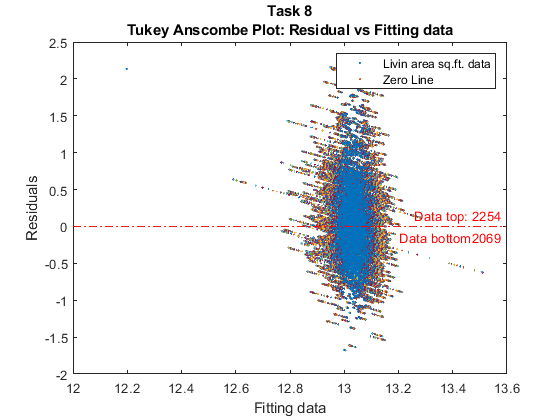

Above and under the "Zero Line" 
 Top:		 2254
 Bottom:	 2069
 Std.dev.:	 130.814755

tukeyAnscombePlot(prices_test_pred, residual_test, "8");

#### Histogram of the residuals

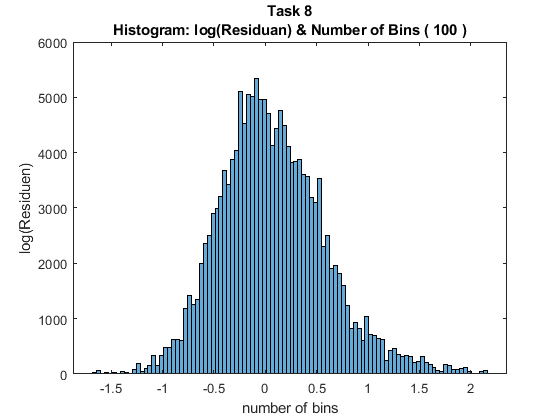

figure;
nbins = 100;
histogram(residual_test, nbins);
title({'Task 8','Histogram: log(Residuan) & Number of Bins ( 100 )'});
ylabel('log(Residuen)'); 
xlabel('number of bins'); 

The histogram is almost very well balanced in the random iterations. No much left or right skewed anymore.

fprintf("The Standard deviation of the residuals is: " + std(residual_many_features_log));

The Standard deviation of the residuals is: 0.19925

The standard deviation is better then before (see Task 3).

#### Task 9

*"What would be needed if you wanted to optimize the MAPE as cost function instead of the ‘residual-sum-of-squares’?*

*Try to derive the corresponding formulas and give a sketch of the resulting algorithm e.g. in pseudo-code."*

So I have the APE:  $\sum \left|\;\frac{y-y_{\textrm{pred}} \;\;}{y_{\textrm{pred}} \;\;}\;\right|\;$

The  I take the Cost-Functione:   $J\left(\theta \right)=\frac{1}{2m}{\left(X*\textrm{theta}-y\right)}^2 \;$,

replace it with MAPE  =  mean (APE 